# **Transfer Learning using AlexNet and Dog Breed Classifier Dataset**

You will need to have modified dataset.

- Download the "Dog Breed Identification" dataset from (https://www.kaggle.com/c/dog-breed-identification/data)

- Run "ModifyDataset.mlx" script to modify the dataset into directory wise categories

# Train

## Set up testing data

rootFolder = 'test';

LabelData = readtable('.\labels.csv', 'Format', '%C%C');
BreedLabels = string(transpose(table2cell(unique(LabelData(:,'breed')))));

BreedCount = numel(BreedLabels)

BreedCount = 120


testDS = imageDatastore(fullfile(rootFolder, BreedLabels), 'LabelSource', 'foldernames');
testDS.ReadFcn = @readFunctionTrain;

## Import GoogLeNet trained with Transfer Learning

Importing trained network for some manual validation and results.

GoogLeNet_convnet = trainedNetwork_1;

## Test classifer

[labels,err_test] = classify(GoogLeNet_convnet, testDS, 'MiniBatchSize', 64);

## Determine overall accuracy

GoogLeNet_confMat = confusionmat(testDS.Labels, labels);
GoogLeNet_confMat = GoogLeNet_confMat./sum(GoogLeNet_confMat,2);
OverallAccuracy = mean(diag(GoogLeNet_confMat))

OverallAccuracy = 0.9394

BreedAcc = diag(GoogLeNet_confMat).';
int_confMat = int64(GoogLeNet_confMat .* 10000)

int_confMat = 120×120 int64 matrix
    9625       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0
       0    9569       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0      86       0       0       0       0       0       0       0       0       0       0       0       0       0      86       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0
       0       0   10000       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0   

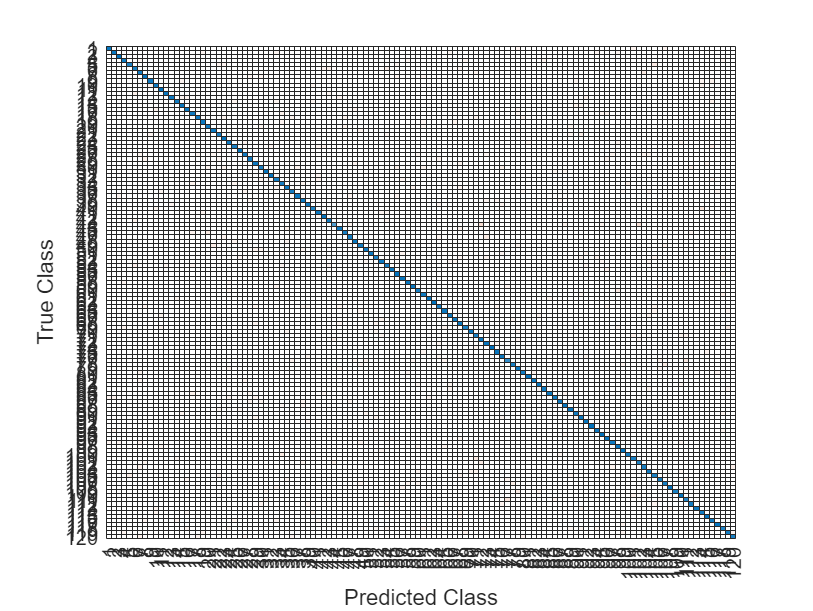

confusionchart(int_confMat)